%% Gaussian Chaff Simulation with Time Dynamics
% This script models the distribution and movement of chaff particles
% initially placed in a Gaussian distribution. Features include:
% - Representative lengths
% - Dynamic position changes over time
% - Effect of gravity (deceleration in Z-direction)
% - Gradual orientation changes

%% Parameters
% Define global parameters for the simulation
lambda = 10e-2;          % Wavelength in meters (example: 10 cm)
meanLength = lambda / 2; % Mean chaff length
stdDev = 0.01;           % Standard deviation of chaff lengths (1 cm)
minLength = 0.01;        % Minimum chaff length (1 cm)
numParticles = 1000;     % Number of chaff particles

% Orientation parameters
azimuthRange = [0, 2*pi]; % Azimuth angles (radians)
elevationRange = [0, pi]; % Elevation angles (radians)

% Gaussian position distribution parameters
mu = [0, 0, 10]; % Mean position (center at [0, 0, 10])
sigma = [5, 5, 2]; % Standard deviations in X, Y, Z directions

% Time evolution parameters
timeSteps = 500;          % Number of time steps for simulation
dt = 0.1;                % Time step duration (seconds)
velocityMean = 2;        % Mean velocity magnitude (m/s)
velocityStdDev = 0.5;    % Velocity standard deviation (m/s)
angularChange = 0.1;     % Maximum change in orientation angles per step (radians)
g = 9.81;                % Gravity (m/s^2) for simplistic downward acceleration

%% Generate Chaff Lengths
chaffLengths = meanLength + stdDev * randn(numParticles, 1);
chaffLengths(chaffLengths < minLength) = minLength;

%% Initial Positions and Orientations
% Generate Gaussian-distributed positions
x = mu(1) + sigma(1) * randn(numParticles, 1);
y = mu(2) + sigma(2) * randn(numParticles, 1);
z = mu(3) + sigma(3) * randn(numParticles, 1);

% Generate random orientations
azimuth = azimuthRange(1) + (azimuthRange(2) - azimuthRange(1)) * rand(numParticles, 1);
elevation = elevationRange(1) + (elevationRange(2) - elevationRange(1)) * rand(numParticles, 1);

% Generate initial velocities
velocity = velocityMean + velocityStdDev * randn(numParticles, 1);
vx = velocity .* cos(azimuth) .* sin(elevation);
vy = velocity .* sin(azimuth) .* sin(elevation);
vz = velocity .* cos(elevation);

%% Time Evolution of Positions and Orientations
positions = zeros(numParticles, 3, timeSteps); % To store positions over time
orientations = zeros(numParticles, 3, timeSteps); % To store orientation vectors over time

for t = 1:timeSteps
    % Update positions with velocity and gravity
    x = x + vx * dt;
    y = y + vy * dt;
    z = z + vz * dt - 0.5 * g * dt^2; % Gravity affects Z position

    % Prevent particles from going below Z=0 (ground level)
    z(z < 0) = 0;

    % Randomly update orientations
    azimuth = azimuth + angularChange * (2 * rand(numParticles, 1) - 1);
    elevation = elevation + angularChange * (2 * rand(numParticles, 1) - 1);
    elevation = max(0, min(pi, elevation)); % Clamp elevation between 0 and pi

    % Calculate orientation vectors
    u = cos(azimuth) .* sin(elevation) .* chaffLengths;
    v = sin(azimuth) .* sin(elevation) .* chaffLengths;
    w = cos(elevation) .* chaffLengths;

    % Store positions and orientations
    positions(:, :, t) = [x, y, z];
    orientations(:, :, t) = [u, v, w];
end

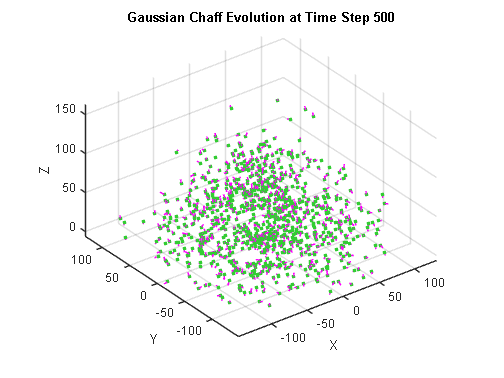

%% Visualisation of Time Evolution
figure;
for t = 1:timeSteps
    scatter3(positions(:, 1, t), positions(:, 2, t), positions(:, 3, t), 10, 'filled', 'MarkerFaceColor', [0.2, 0.8, 0.2]);
    hold on;
    quiver3(positions(:, 1, t), positions(:, 2, t), positions(:, 3, t), ...
        orientations(:, 1, t), orientations(:, 2, t), orientations(:, 3, t), 0.5, 'Color', 'm');
    hold off;
    title(sprintf('Gaussian Chaff Evolution at Time Step %d', t));
    xlabel('X'); ylabel('Y'); zlabel('Z');
    grid on; axis equal;
    pause(0.1); % Pause to create animation effect
end